#### Linear advection simulation using Adam-Bashforth scheme, Second Order Backward in space and calculating numerical amplification factor

One-Dimesional linear convection equation is:


$$\frac{\partial u}{\partial t}+c\frac{\partial u}{\partial x}=0$$


Discretizng using AB-BS gives


$$	u^{n+2*}_i=u^{n+1}_i-\frac{3CFL}{2\times2}\left(u^{n+1}_{i-2}-4u^{n+1}_{i-1}+3u^{n+1}_{i}\right)+\frac{CFL}{2\times2}\left(u^{n}_{i-2}-4u^{n}_{i-1}+3u^{n}_{i}\right)$$


Corrector step is:


$$u^{n+2}_i=u^{n+1}_i-\frac{CFL}{2}\left(u^{n+2*}_{i-2}-4u^{n+2*}_{i-1}+3u^{n+2*}_{i}\right)-\frac{CFL}{2}\left(u^{n+1}_{i-2}-4u^{n+1}_{i-1}+3u^{n+1}_{i}\right)$$


Converting the above equation in the spectral plane, we get


$$U^{n+2*}=U^{n+1}-\frac{3CFL}{2\times2}\left(3U^{n+1}-4U^{n+1}\exp(-ikh)+U^{n+1}\exp(-2ikh)\right)+\frac{CFL}{2\times2}\left(3U^{n}-4U^{n}\exp(-ikh)+U^{n}\exp(-2ikh)\right),$$



$$
U^{n+2}=U^{n+1}-\frac{CFL}{2\times2}\left(3U^{n+2*}-4U^{n+2*}\exp(-ikh)+U^{n+2*}\exp(-2ikh)\right)-\frac{CFL}{2\times2}\left(3U^{n+1}-4U^{n+1}\exp(-ikh)+U^{n+1}\exp(-2ikh)\right)$$


Numerical amplification factor is:


$$G^{(1)}=1-\frac{3CFL}{2\times2}\left(3-4\exp(-ikh)+\exp(-2ikh)\right)+\frac{CFL}{2G^{(1)}}\left(3-4\exp(-ikh)+\exp(-2ikh)\right)$$


where, $G^{(1)}=\frac{U^{n+2*}}{U^{n+1}} = \frac{U^{n+1}}{U^{n}}.$ It has two roots Solving for $G^{(1)}$ and substitute that in the corrector equation gives

 
$$G=1-\frac{G^{(1)}.CFL}{2\times2}\left(3-4\exp(-ikh)+\exp(-2ikh)\right)-\frac{CFL}{2\times2}\left(3-4\exp(-ikh)+\exp(-2ikh)\right).$$


clc
clear all
close all
format long

Domain Length is 2 $\pi$ and divided into 501 points. Initial condtion used is sin(x) with wave number 1.

l=2*pi;
n=501;
k=1;
x=linspace(0,l,n);
y=sin(k*x);

Delete the last point to avoid repetion, because $y(2\pi)=y(0)$

x(end)=[];
y(end)=[];
dx=l/(n-1);

Flow time is 5 s and calculate $\Delta t$ from CFL number

T=5;
c=1;
cfl=0.4;
dt=cfl/c*dx;
nt=round(T/dt);

Solving PDE

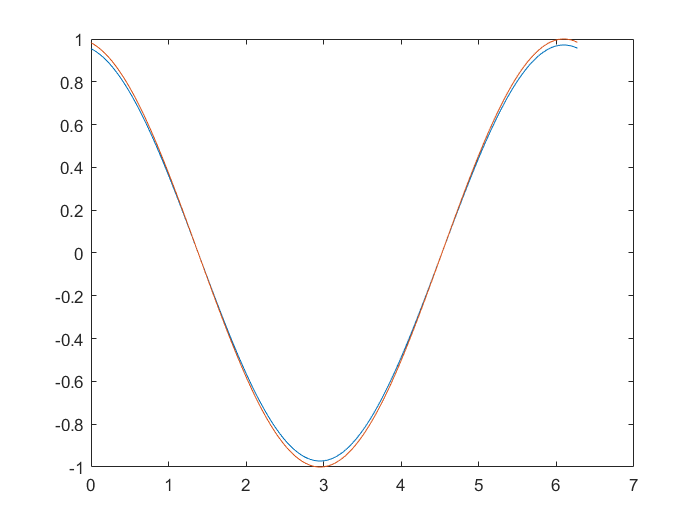

qw1=round(nt/10); % plot number of framed
y_0=y;
t2=dt;
y_1=sin(k*(x-c*t2)); % AB method is not sef starting so we give one more IC
for i =2:nt
        dy_1=PerDerivative_L1R0(y_1,dx);
        dy0=PerDerivative_L1R0(y_0,dx);
        yn=y_1-3/2*c*dt*dy_1+1/2*c*dt*dy0;
        t1=dt*(i);
        yex=sin(k*(x-c*t1)) ;

        y_0=y_1;
        y_1=yn;
if mod(i,qw1)==0
    plot(x,yn,x,yex)
    drawnow
end
kh=dx*k;
Fs=1/dx;
Ts=dx;
[YfreqD,freqRng] = positiveFFT(yn,Fs,yex);
fft_mag(i)=max((YfreqD));

end

Numerical amplification factor is:

gsim=min(fft_mag(2:end)./fft_mag(1:end-1));
fprintf('Numerical amplification factor from simulation =\n %f%+fj\n',real(gsim),imag(gsim));

Numerical amplification factor from simulation =
 0.999956-0.005026j


Theoritical amplification factor is slightly tricky, We should find roots of $G^{(1)} equation

syms G_ex kh1 cfl1
g1=G_ex-(1-3/2*cfl1*(1-exp(-1i*kh1))+1/2*cfl1/G_ex*(1-exp(-1i*kh1)));
eq1=solve(g1,G_ex);
disp('Roots of G1 are')

Roots of G1 are


disp(eq1)

$$\begin{array}{l} \left(\begin{array}{c} \frac{{\mathrm{e}}^{-{\mathrm{kh}}_{1}\,\mathrm{i}}\,\left(3\,{\mathrm{cfl}}_{1}+2\,{\mathrm{e}}^{{\mathrm{kh}}_{1}\,\mathrm{i}}-3\,{\mathrm{cfl}}_{1}\,{\mathrm{e}}^{{\mathrm{kh}}_{1}\,\mathrm{i}}+\sigma_{1}\right)}{4}\\ \frac{{\mathrm{e}}^{-{\mathrm{kh}}_{1}\,\mathrm{i}}\,\left(3\,{\mathrm{cfl}}_{1}+2\,{\mathrm{e}}^{{\mathrm{kh}}_{1}\,\mathrm{i}}-3\,{\mathrm{cfl}}_{1}\,{\mathrm{e}}^{{\mathrm{kh}}_{1}\,\mathrm{i}}-\sigma_{1}\right)}{4} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{4\,{\mathrm{e}}^{2\,{\mathrm{kh}}_{1}\,\mathrm{i}}-18\,{{\mathrm{cfl}}_{1}}^{2}\,{\mathrm{e}}^{{\mathrm{kh}}_{1}\,\mathrm{i}}+9\,{{\mathrm{cfl}}_{1}}^{2}\,{\mathrm{e}}^{2\,{\mathrm{kh}}_{1}\,\mathrm{i}}+9\,{{\mathrm{cfl}}_{1}}^{2}+4\,{\mathrm{cfl}}_{1}\,{\mathrm{e}}^{{\mathrm{kh}}_{1}\,\mathrm{i}}-4\,{\mathrm{cfl}}_{1}\,{\mathrm{e}}^{2\,{\mathrm{kh}}_{1}\,\mathrm{i}}} \end{array}$$

Displaying G1 and G2

G_ex1=(exp(-kh*1i)*(3*cfl + 2*exp(kh*1i) - 3*cfl*exp(kh*1i) + (4*exp(kh*2i) - 18*cfl^2*exp(kh*1i) + 9*cfl^2*exp(kh*2i) + 9*cfl^2 + 4*cfl*exp(kh*1i) - 4*cfl*exp(kh*2i))^(1/2)))/4;
G_ex2=(exp(-kh*1i)*(3*cfl + 2*exp(kh*1i) - 3*cfl*exp(kh*1i) - (4*exp(kh*2i) - 18*cfl^2*exp(kh*1i) + 9*cfl^2*exp(kh*2i) + 9*cfl^2 + 4*cfl*exp(kh*1i) - 4*cfl*exp(kh*2i))^(1/2)))/4;
fprintf('Numerical amplification factor from theory G1 =\n %f%+fj\n',real(G_ex1),imag(G_ex1));

Numerical amplification factor from theory G1 =
 0.999956-0.005026j


fprintf('Numerical amplification factor from theory G2 =\n %f%+fj\n',real(G_ex2),imag(G_ex2));

Numerical amplification factor from theory G2 =
 -0.000003-0.002513j


Plotting the frequncy 

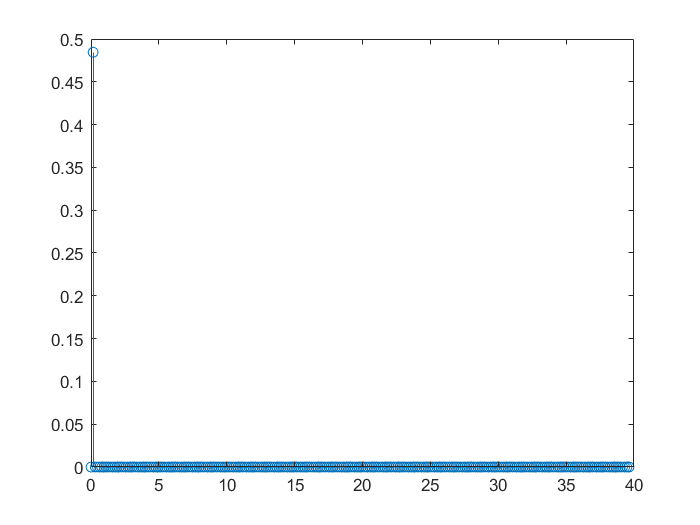

stem(freqRng,abs(YfreqD));

[M,I] = max(abs(YfreqD));
fprintf('Frequency of the FFT signal is %f', freqRng(I))

Frequency of the FFT signal is 0.159155

fprintf('Frequency of the input signal is %f', k/2/pi)

Frequency of the input signal is 0.159155